Load tide gauge data, plot time series

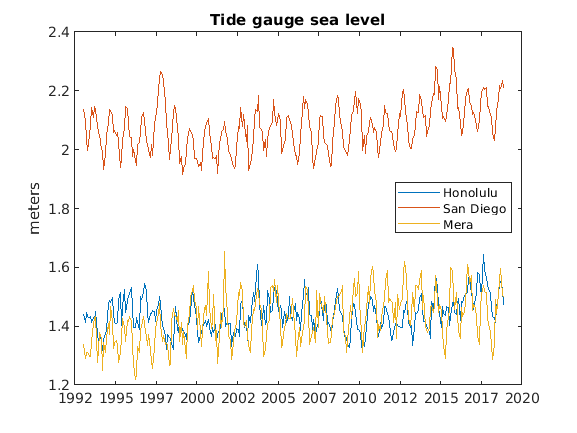

load TGdata
plot(TG.t,TG.sl)
datetick
ylabel('meters')
title('Tide gauge sea level')
legend('Honolulu','San Diego','Mera')
legend('Location','East')

The tide gauge data are referenced to benchmarks on land, so their mean values are arbitrary for our purposes.  We're concerned about fluctuations and trends about the means.  Let's look at the San Diego time series.

Example 1: Use regress to fit a linear trend and mean 

t = TG.t;
sl_sd = TG.sl(:,2);
x = [t-mean(t) ones(length(t),1)];   
b = regress(sl_sd,x);

The trend is b(1), the offset is b(2).  Because time is in days and sea level is in meters, the trend is in m/day.  To convert to mm/yr

tr = b(1)*1000*365.25;

Trend is 4.27 mm/yr

Plot the trend + mean on top of the time series

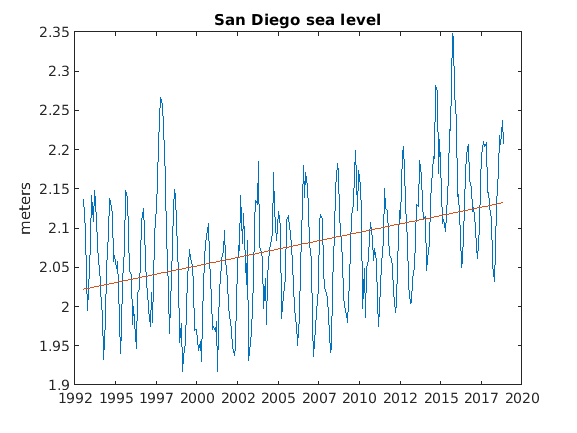

plot(t,sl_sd,t,x*b)
datetick
ylabel('meters')
title('San Diego sea level')

Plot the time series with the trend and mean removed:

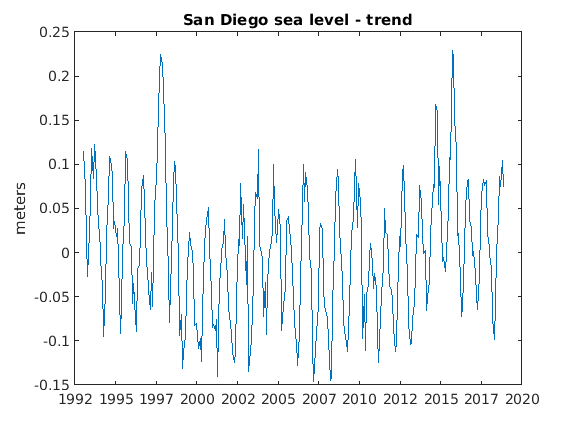

plot(t,sl_sd-x*b)
datetick
ylabel('meters')
title('San Diego sea level, detrended')

Example 2: Use regress to fit a linear trend, mean, and seasonal cycle to the San Diego time series.  Define the seasonal cycle as a sum of cosines and sines at the annual frequency, and twice the annual frequency

arg = 2*pi*t/365.25;
x2 = [t-mean(t) ones(length(t),1) cos(arg) sin(arg) cos(2*arg) sin(2*arg)];   
b2 = regress(sl_sd,x2);
tr2 = b2(1)*365.25*1000;

The trend is now 4.08 mm./yr

Plot the trend + mean + seasonal cycle on top of the time series

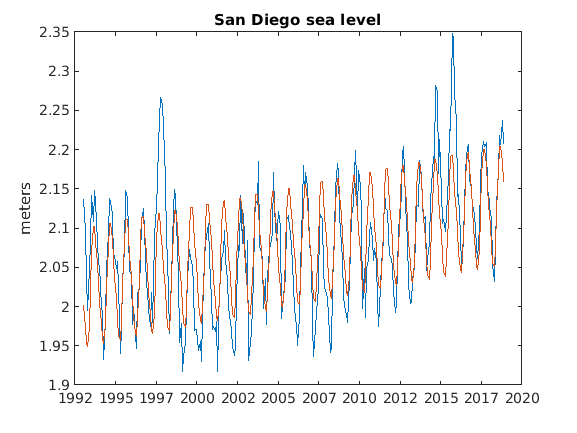

plot(t,sl_sd,t,x2*b2)
datetick
ylabel('meters')
title('San Diego sea level')

Plot the anomaly time series with the trend, mean, and seasonal cycle removed

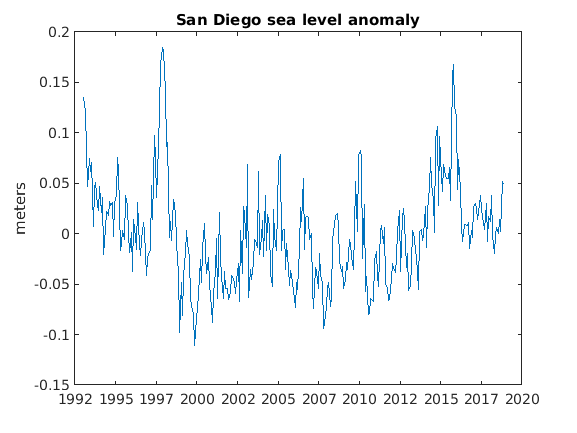

plot(t,sl_sd-x2*b2)
datetick
ylabel('meters')
title('San Diego sea level anomaly')